# Fourier Transform

### Basic example: Random set

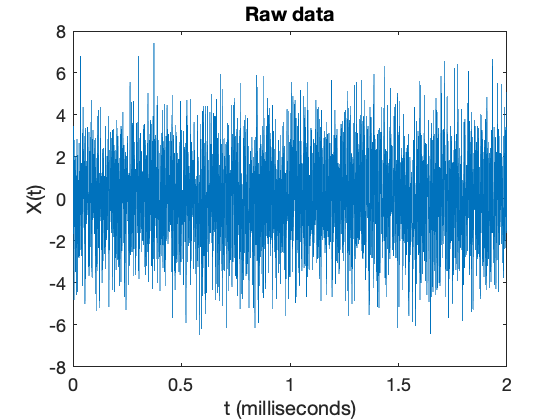

file = readtable('data.csv');
t = file{:,1};
X = file{:,2};
plot(t, X)
title('Raw data')
xlabel('t (milliseconds)')
ylabel('X(t)')


Fs = 20000; % Sampling frequency 
L = size(X,1) % Length of signal

L = 4000

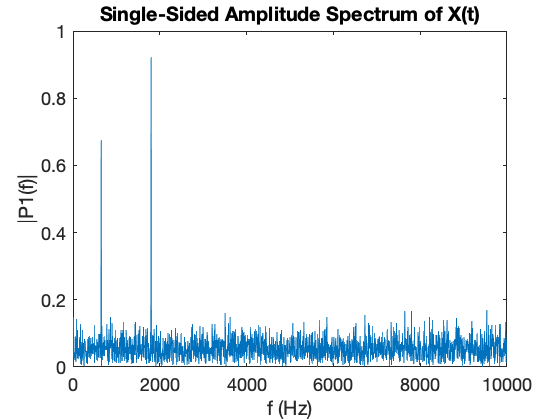

%T = 1/Fs; % Sampling period

Y = fft(X); % Fourier Transform
P = abs(Y*2/L); % Realize and Normalize
f = Fs*(0:L-1)/L; % Make bin widths
clf
plot(f(1:2000), P(1:2000)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

### Signal from LIGO detector

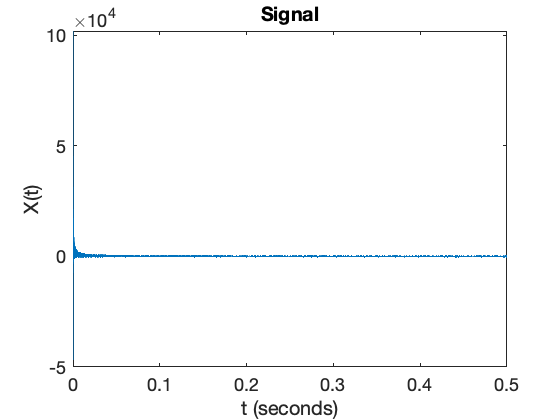

file = readtable('Quiz3DataFile.csv');
t = file{:,1}; % time (seconds)
X = file{:,2}; % detected signal
plot(t,X)
title('Signal')
xlabel('t (seconds)')
ylabel('X(t)')

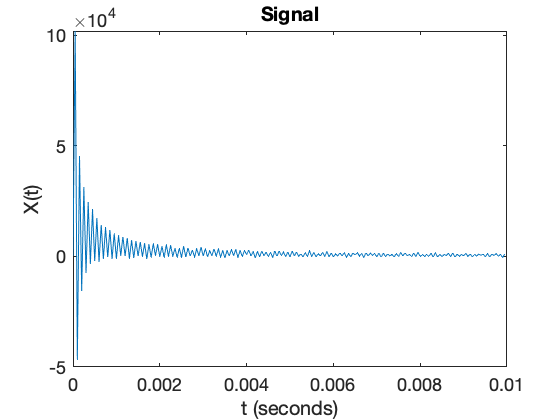

plot(t(1:200), X(1:200))
title('Signal')
xlabel('t (seconds)')
ylabel('X(t)')

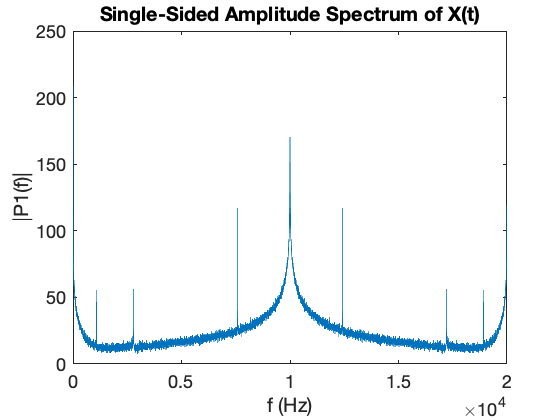


% Large signal from 0 to 0.001 seconds,
% then tapers off

Fs = 20000; % Sampling frequency 
% should be twice the frequency of the signal
% period looks to be around 0.0001 seconds
% so frequency of around 10000 Hz
% so sampling frequency of 20000 Hz
L = size(X,1); % Data length (Length of signal)

Y = fft(X); % Fourier Transform
P = abs(Y*2/L); % Realize and Normalize
f = Fs*(0:L-1)/L; % Make bin widths

% FFT produces characteristic frequencies and their
% mirror image

plot(f(1:10000), P(1:10000)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

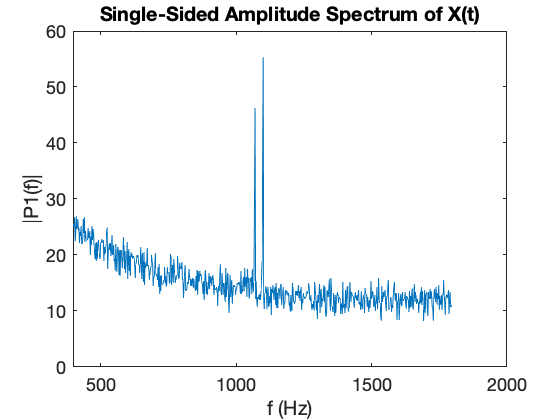


% The spike in the middle represents the large
% signal at first few milliseconds, everything 
% after is a reflection
% three characteristic frequencies below spike

% difficult to tell if this large spike in the
% middle is 'characteristic'

% First characteristic frequency is actually 
% two seperate frequencies
plot(f(200:900), P(200:900)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

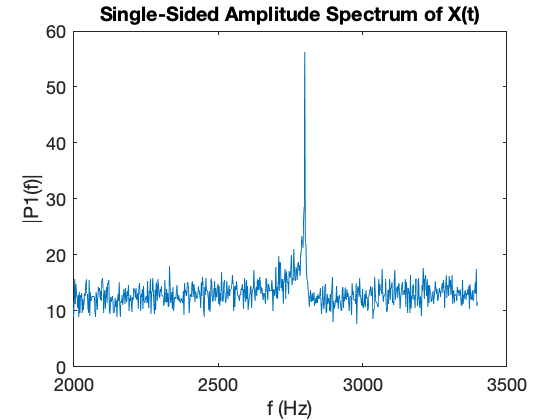

% First two characteristic frequencies are
% 1070 Hz, 1110 Hz 

plot(f(1000:1700), P(1000:1700)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

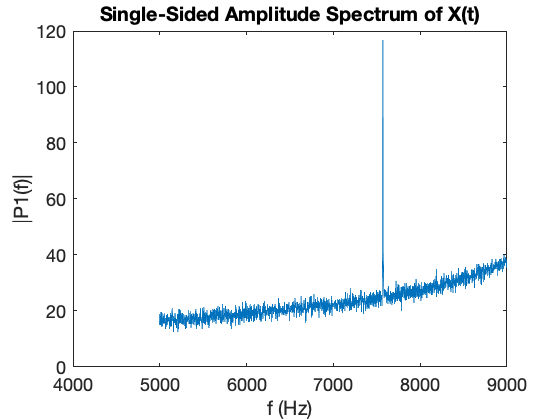

% Third characteristic freauency
% 2798 Hz

plot(f(2500:4500), P(2500:4500)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

% Fourth char freq
% 7572 Hz


### Signal generated in Matlab: corrupted with zer-mean noise

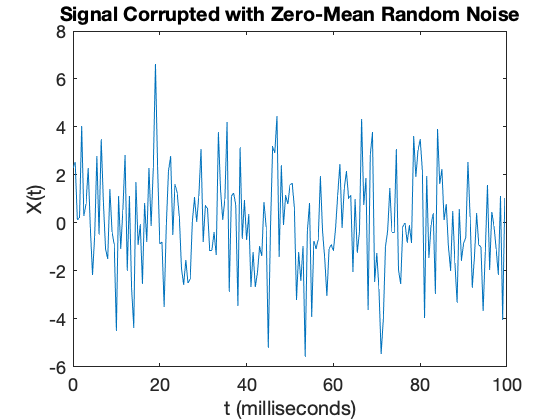

Fs = 2000; % Sampling frequency 
T = 1/Fs; % Sampling period
L = 4000; % Length of signal
t = (0:L-1)*T; % Time vector

S = 0.7 * sin(2*pi*65*t) + sin(2*pi*180*t); 
% Signal Values 
X = S + 2*randn(size(t)); % Adding in noise

set(groot,'DefaultAxesFontSize',18)
figure(1)
plot(1000*t(1:200),X(1:200)) 
%Changed time to milliseconds and zoomed
% in to first 200 points
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

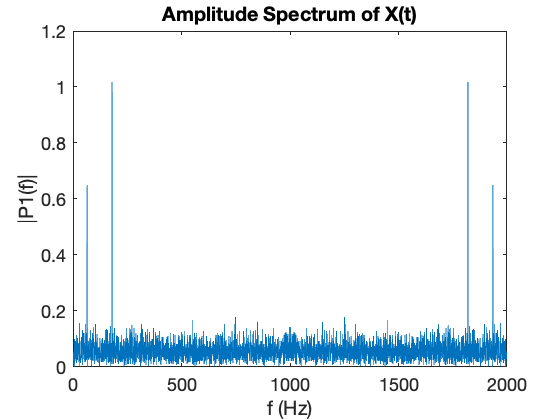


Y = fft(X);% Fast Fourier Transform
P = abs(Y*2/L); % abs value and Normalize
% abs() removes the negative and imaginary
% 2/L normalizes the amplitudes
f= Fs*(0:L-1)/L; % Frequency list in Hz

figure(2)
plot(f,P)
title('Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

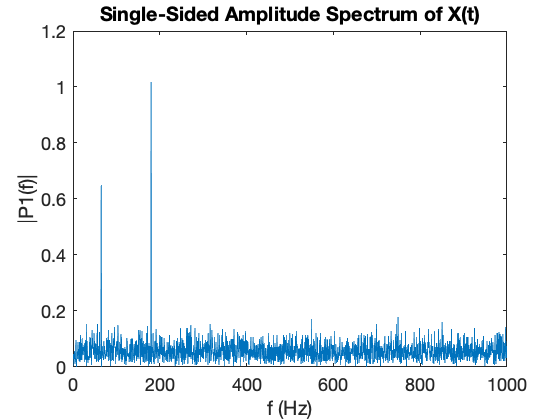


% We see two signals we expected and 2 we didn't expect
% Everything after 1/2 Fs is a reflection about 1/2 Fs 
% To correct only plot the first half

plot(f(1:L/2),P(1:L/2))
%Looking at first 2000 points (0-1000 Hz) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

### Example: Guitar string

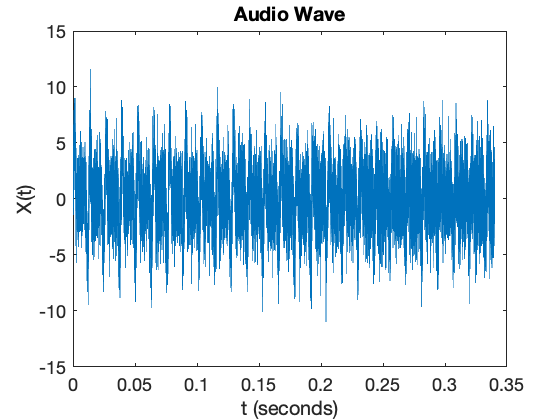

file = readtable('guitar_low_E.csv');
t = file{:,1};
X = file{:,2};
plot(t,X)
title('Audio Wave')
xlabel('t (seconds)')
ylabel('X(t)')

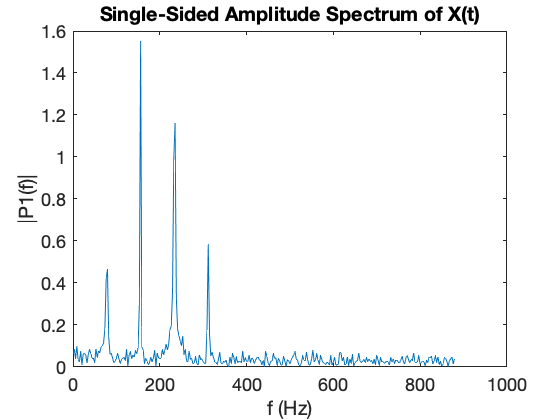


Fs = 44100; % Sampling frequency 
L = size(X,1); % Data length (Length of signal) (15000)

Y = fft(X); % Fourier Transform
P = abs(Y*2/L); % Realize and Normalize
f = Fs*(0:L-1)/L; % Make bin widths

plot(f(1:300), P(1:300)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')


$$f\lambda =\sqrt{\frac{T}{\rho }}$$
         
$$T=f^2 \lambda^2 \rho$$
        

Can calculate $T_0$ as we know f's needed, use $\lambda =2L$ can get $\rho$


$$C=\frac{\Delta T}{\left(\Delta \frac{L}{L}\right)}$$
           
$$\Delta L=\frac{\left(T_1 -T_0 \right)L}{C}$$
           

 
$$\mathrm{peg}\;\mathrm{turns}=\frac{\Delta L}{0\ldotp 005\;\left(\frac{m}{\mathrm{turn}}\right)}=\;$$

$$\frac{1}{0\ldotp 005\;\left(\frac{m}{\textrm{turn}}\right)}\;\frac{\left(T_1 -T_0 \right)L}{C}\;$$



$$\mathrm{peg}\;\mathrm{turns}\;=\frac{1}{0\ldotp 005\;\left(\frac{m}{\textrm{turn}}\right)}\frac{\left.{\left(f\right.}_1^2 \lambda^2 \rho -f_0^2 \lambda^2 \rho \right)}{C}=\frac{4L^3 \rho }{0\ldotp 005\;\left(\frac{m}{\textrm{turn}}\right)}\frac{\left(f_1^2 -f_0^2 \right)}{C}\;$$


### Signal generated in Matlab: Practice Test

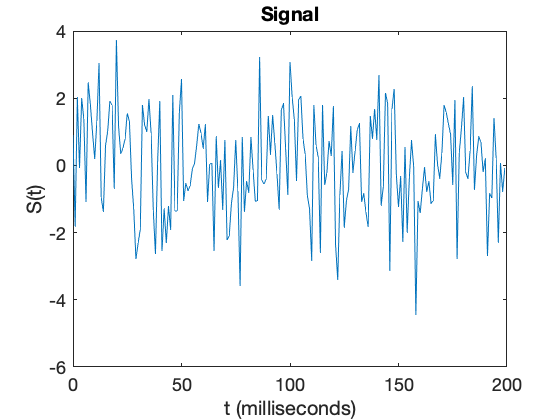

Fs = 1000; % Sampling frequency 
T = 1/Fs; % Sampling period
L = 5000; % Length of signal
t = (0:L-1)*T; % Time vector
A=1;
S = A*cos(100*pi*t-50).*sin(150*pi*t+100)+...
    1.5*A*randn(size(t));
% plot the signal
figure
plot(Fs*t(1:200),S(1:200)) 
title('Signal')
xlabel('t (milliseconds)') 
ylabel('S(t)')

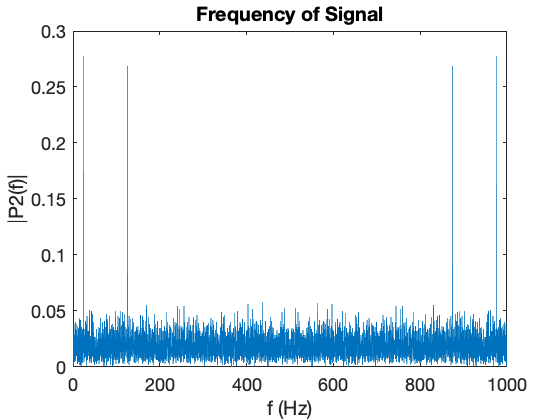

%FFT
Y = fft(S);
P2=abs(Y/L); %strength of the FFT signal 
f = Fs*(0:L-1)/L; %frequency bins figure
plot(f,P2)
title('Frequency of Signal')
xlabel('f (Hz)')
ylabel('|P2(f)|')

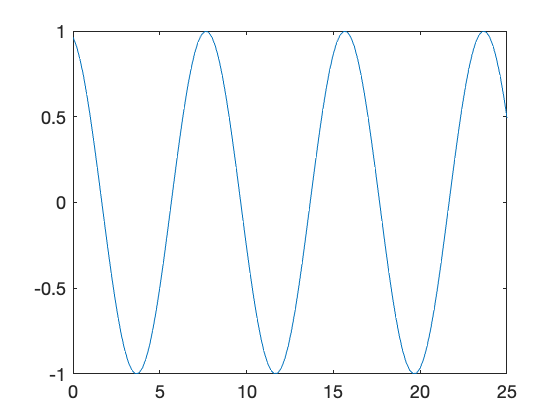


S = A*cos(2*pi*25*t-50); %frequency of 25 Hz
plot(f,S)
xlim([0,25])